# ELEC5305 Audio Processing Report One

## STFT-Based Speech Enhancement for Noisy Speech

*Author: Chenxin Zhang*

*SID: 540881826*

*Date: 2 September 2026*

*GitHub Repository: https://github.com/Chenx104/elec5305-speech-enhancement*

## 1. Objective

This report aims to complete the speech enhancement experiment using MATLAB. In the experiment, a clean speech is used as input, and Gaussian white noise is added to simulate the noisy recording environment; Then the signal is analyzed by time domain waveform, spectrum and STFT spectrum; Finally, Wiener-style soft mask is used to reduce noise in STFT domain, and the enhancement effect is evaluated by combining image, audio features and SNR improvement [1], [3].

## 2. Background

Digital audio processing first involves sampling: continuous sound signals are converted to discrete-time samples at a fixed sampling rate. The sampling rate of the speech file used in this experiment is 8 kHz, so the highest frequency that can be represented is the Nyquist frequency of 4 kHz. 

The Nyquist frequency is calculated as: 

 $f_N = \frac{f_s}{2} = \frac{8000}{2} = 4000 \text{ Hz}$.

The noisy speech signal can be represented as:

 $y\left\lbrack n\right\rbrack =x\left\lbrack n\right\rbrack +d\left\lbrack n\right\rbrack$, 

where x[n] is the clean speech signal, d[n] is the added noise, and y[n] is the noisy speech signal.

The FFT can analyze the overall frequency components of the signal, but speech is a non-stationary signal, and its frequency content will change with time. Therefore, using FFT only once cannot reflect when different frequency components occur. The STFT divides the signal into short-time frames, and calculates the FFT after windowing each frame, so as to obtain the frequency information that changes with time, i.e. the spectrogram [2], [5].

The STFT of a windowed speech frame is written as:

$X(k,m) = \sum_{n=0}^{L-1} x[n+mR]w[n]e^{-j2\pi kn/N}
$, 

where L is the window length, R is the hop size, w[n] is the Hann window, N is the FFT length, k is the frequency-bin index, and m is the frame index.

The Hann window and frame overlap are very important to STFT analysis: windowing can reduce spectral leakage, and frame overlap is helpful to the smoothness of reconstruction [2]. In speech enhancement, the dominant part of noise can be suppressed in the time-frequency domain, while preserving speech components as much as possible [1], [3].

The Wiener-style soft mask used for enhancement is:

$H(k,m) = \frac{|X(k,m)|^2}{|X(k,m)|^2 + |D(k,m)|^2 + \epsilon}$,

The enhanced STFT is obtained by:

$\hat{X}(k,m) = H(k,m)Y(k,m)$,

where H(k,m) is the soft mask, D(k,m) is the noise STFT, Y(k,m) is the noisy speech STFT, and X-hat(k,m) is the enhanced STFT.

## 3. Methodology and Implementation

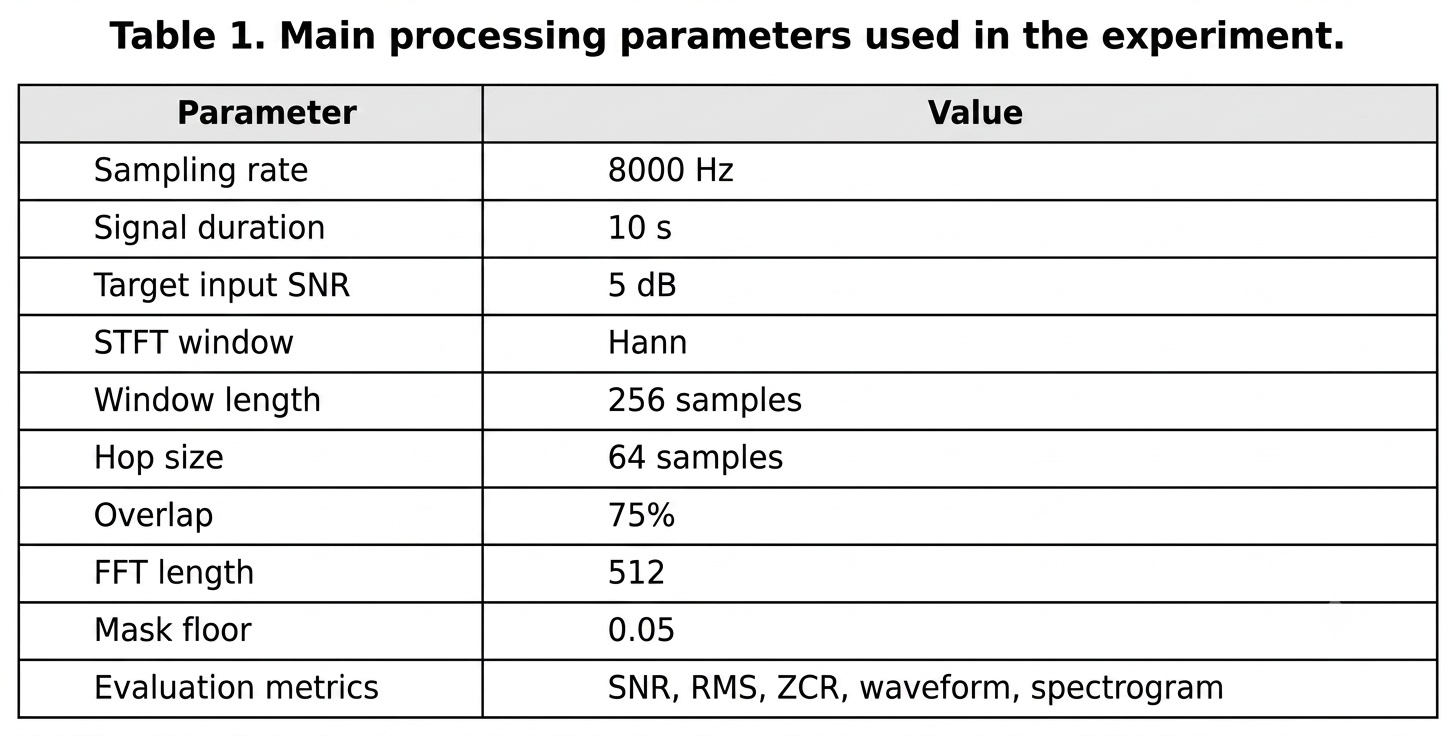

This report uses a short American English speech recording from the Open Speech Repository as the clean input signal [4]. The signal is read in MATLAB using the audioread function. Since the audio file is mono and has a sampling rate of 8 kHz, it can be analysed directly without stereo-to-mono conversion or resampling. To keep the report concise, only the first 10 seconds of the recording are used.

The whole process includes five main stages. First, the time-domain waveform of the clean speech signal is plotted. Second, white Gaussian noise is added to generate a noisy speech signal with a controlled signal-to-noise ratio. Third, FFT-based spectrum analysis and STFT spectrograms are used to compare the clean and noisy speech signals. Fourth, a Wiener-style soft mask is applied in the STFT domain to suppress time-frequency components dominated by noise. Finally, the enhanced speech signal is reconstructed using the overlap-add method, and the processing result is evaluated using waveform, spectrogram, signal-to-noise ratio, and audio feature comparisons [1], [2], [3].

Because the noise in this experiment is artificially added, this is a controlled experiment. The known clean speech signal and noise signal are used to construct an oracle Wiener-style mask, which clearly demonstrates the principle of speech enhancement in the STFT domain [1], [3]. In real application scenarios, clean speech signals are usually unavailable, so the noise power and speech power need to be estimated from the observed noisy speech signal [1], [3].

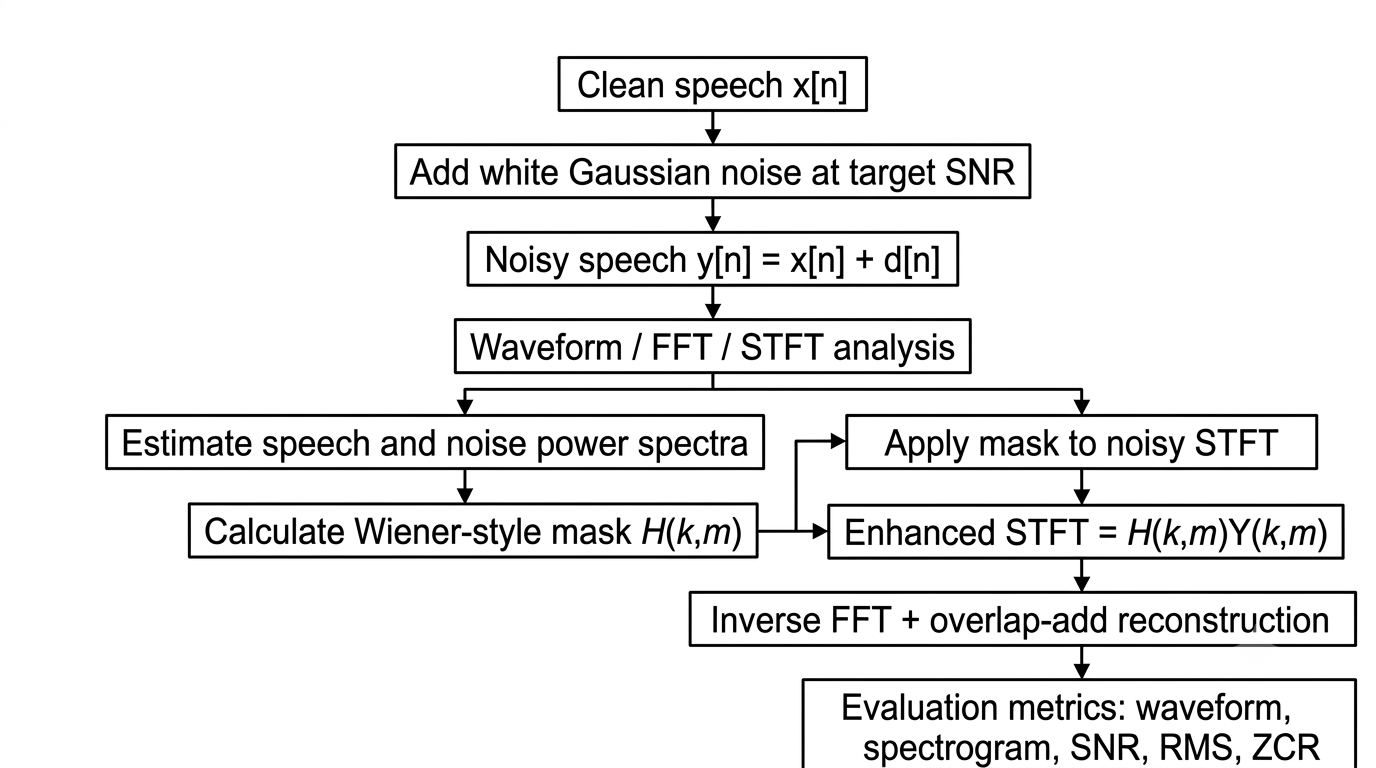

The following flowchart summarises the complete processing pipeline from clean speech input to noisy speech generation, STFT-domain masking, signal reconstruction, and final evaluation.

## 4. Code and Results

This section shows the MATLAB implementation process and experimental results of speech enhancement experiment. The code is divided into several clear stages to facilitate the tracking of the complete processing flow of the signal from the original clean speech, noisy speech to the enhanced output speech.

%% 4.1 Setup and Load Clean Speech

clear; close all; clc;

% Make random noise repeatable
rng(0);

% Get the folder where this Live Script is saved
scriptPath = matlab.desktop.editor.getActiveFilename;
scriptFolder = fileparts(scriptPath);

% Load clean speech signal from the same folder as this Live Script
audioFile = fullfile(scriptFolder, 'clean_speech.wav');
[x, fs] = audioread(audioFile);

% Convert to mono if needed
if size(x, 2) > 1
    x = mean(x, 2);
end

% Normalise amplitude to avoid clipping
x = x / max(abs(x));

% Use the first 10 seconds to keep the report concise
duration = 10;
N = min(length(x), duration * fs);
x = x(1:N);

% Time axis in seconds
t = (0:length(x)-1) / fs;

fprintf('Sampling rate: %d Hz\n', fs);

Sampling rate: 8000 Hz


fprintf('Signal duration: %.2f seconds\n', length(x)/fs);

Signal duration: 10.00 seconds


fprintf('Number of samples: %d\n', length(x));

Number of samples: 80000


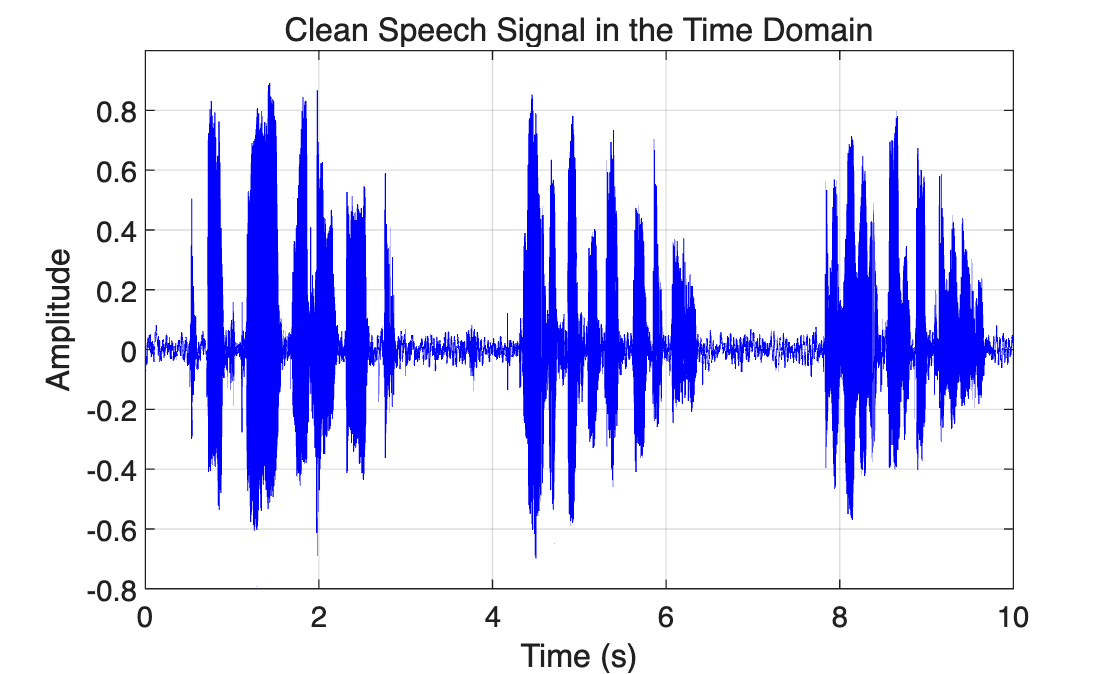


% Plot clean speech waveform
figure;
plot(t, x, 'b');
grid on;
xlabel('Time (s)');
ylabel('Amplitude');
title('Clean Speech Signal in the Time Domain');

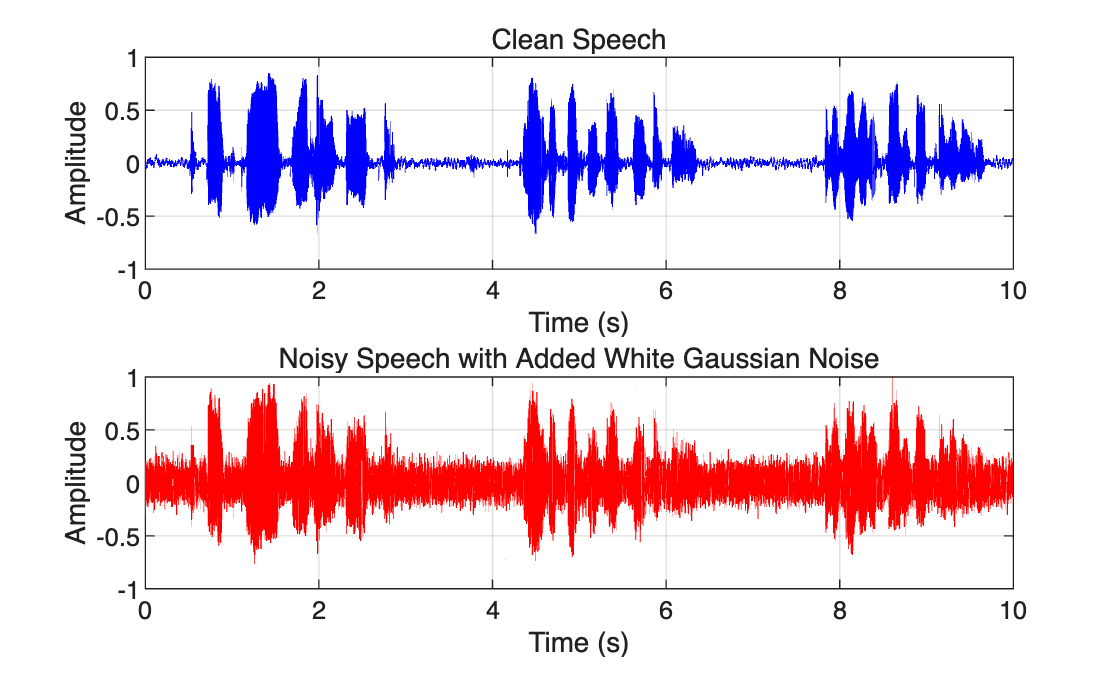

%% 4.2 Add White Gaussian Noise

targetSNR = 5;

% Fixed random seed to make the experiment reproducible
rng(0);
noise = randn(size(x));

signalPower = mean(x.^2);
noisePower = mean(noise.^2);

noiseScale = sqrt(signalPower / (noisePower * 10^(targetSNR/10)));
noise = noiseScale * noise;
y = x + noise;

peakValue = max(abs(y));
if peakValue > 1
    x = x / peakValue;
    noise = noise / peakValue;
    y = y / peakValue;
end

audiowrite(fullfile(scriptFolder, 'noisy_speech.wav'), y, fs);

figure;

subplot(2,1,1);
plot(t, x, 'b');
grid on;
xlabel('Time (s)');
ylabel('Amplitude');
title('Clean Speech');

subplot(2,1,2);
plot(t, y, 'r');
grid on;
xlabel('Time (s)');
ylabel('Amplitude');
title('Noisy Speech with Added White Gaussian Noise');

Compared with the clean speech waveform, the background fluctuation of noisy speech waveform is more obvious, indicating that the Gaussian white noise has been superimposed in the whole time range. Although the overall structure of speech can still be recognized, there is also obvious noise energy in the quiet area. Therefore, it is necessary to further observe the impact of noise with the help of frequency domain analysis and time-frequency analysis.

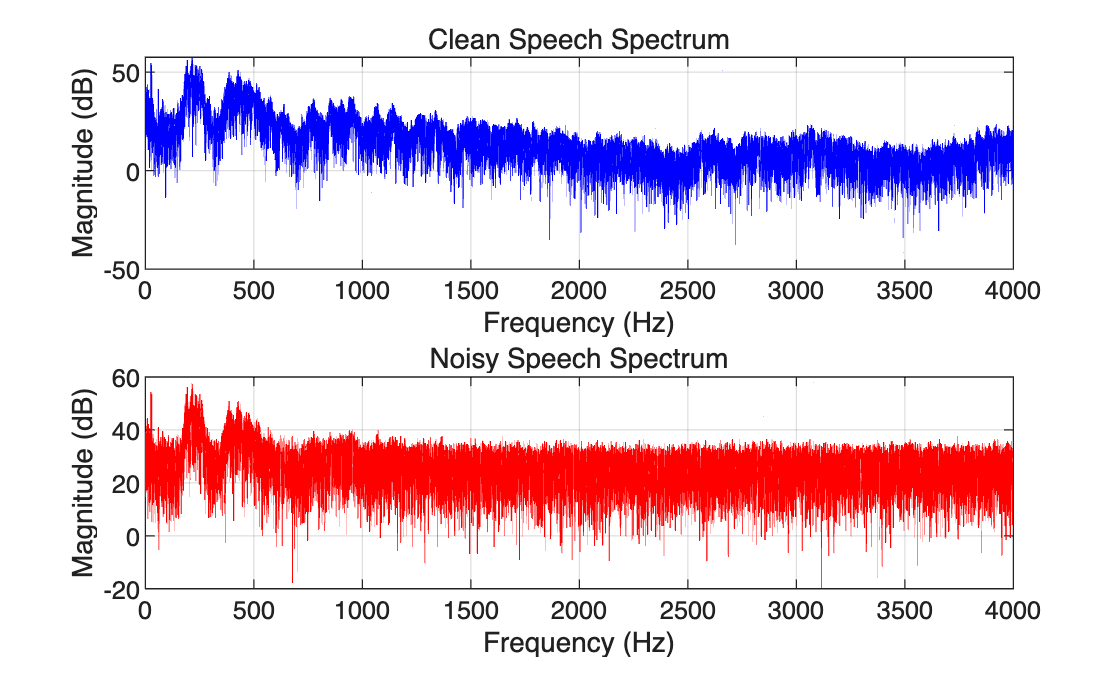


%% 4.3 Frequency-Domain Analysis Using FFT

% Compute FFT length
Nfft = 2^nextpow2(length(x));

% Frequency axis from 0 to Nyquist frequency
f = (0:Nfft/2) * fs / Nfft;

% Compute one-sided magnitude spectra
X = fft(x, Nfft);
Y = fft(y, Nfft);

Xmag = abs(X(1:Nfft/2+1));
Ymag = abs(Y(1:Nfft/2+1));

% Convert to decibels for easier comparison
Xdb = 20 * log10(Xmag + eps);
Ydb = 20 * log10(Ymag + eps);

% Plot spectra
figure;

subplot(2,1,1);
plot(f, Xdb, 'b');
grid on;
xlabel('Frequency (Hz)');
ylabel('Magnitude (dB)');
title('Clean Speech Spectrum');
xlim([0 fs/2]);

subplot(2,1,2);
plot(f, Ydb, 'r');
grid on;
xlabel('Frequency (Hz)');
ylabel('Magnitude (dB)');
title('Noisy Speech Spectrum');
xlim([0 fs/2]);

FFT spectrum shows that the energy of clean speech is mainly concentrated in the lower frequency band, which conforms to the typical characteristics of 8 kHz sampled speech. After adding Gaussian white noise, the spectrum energy becomes more dispersed in the range of 0 – 4 kHz, which shows that the noise affects a wide frequency range, resulting in the decline of speech spectrum definition.

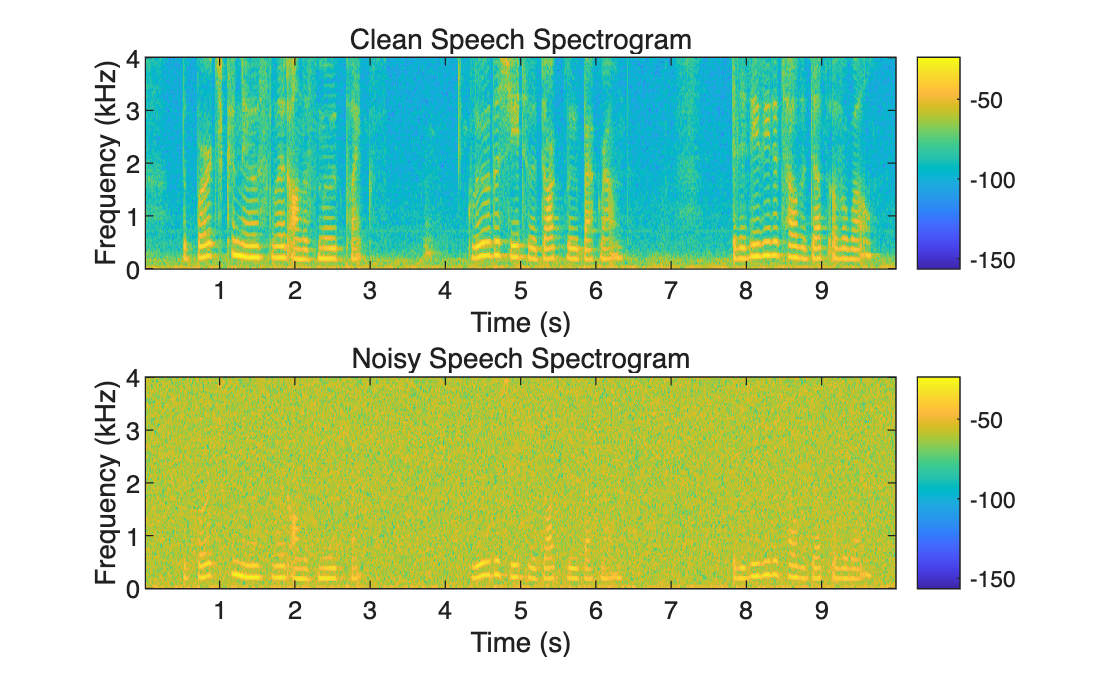

%% 4.4 Time-Frequency Analysis Using STFT Spectrograms

% STFT parameters
winLength = 256;
hopSize = 64;                    % 75% overlap
overlapLength = winLength - hopSize;
nfft = 512;

% Use a Hann window as discussed in the STFT lectures
win = hann(winLength, 'periodic');

% Plot spectrograms
figure;

subplot(2,1,1);
spectrogram(x, win, overlapLength, nfft, fs, 'yaxis');
title('Clean Speech Spectrogram');
xlabel('Time (s)');
ylabel('Frequency (kHz)');
colorbar;

subplot(2,1,2);
spectrogram(y, win, overlapLength, nfft, fs, 'yaxis');
title('Noisy Speech Spectrogram');
xlabel('Time (s)');
ylabel('Frequency (kHz)');
colorbar;

The spectrograms showx that clean speech shows a clear time-frequency structure, while noisy speech shows stronger broadband energy in almost all frequency ranges. This shows that the added Gaussian white noise is distributed in the whole frequency band. Therefore, this report uses a simple Wiener-style soft mask in STFT domain to suppress the time-frequency components dominated by noise.

%% 4.5 STFT-Based Wiener-Style Soft Mask and Overlap-Add Reconstruction

winLength = 256;
hopSize = 64;                      % 75% overlap
nfft = 512;
win = hann(winLength, 'periodic');

numFrames = floor((length(y) - winLength) / hopSize) + 1;
numFreqBins = nfft/2 + 1;

Xstft = zeros(numFreqBins, numFrames);
Ystft = zeros(numFreqBins, numFrames);
Nstft = zeros(numFreqBins, numFrames);

for frame = 1:numFrames
    startIndex = (frame - 1) * hopSize + 1;

    xFrame = x(startIndex:startIndex + winLength - 1) .* win;
    yFrame = y(startIndex:startIndex + winLength - 1) .* win;
    nFrame = noise(startIndex:startIndex + winLength - 1) .* win;

    Xspec = fft(xFrame, nfft);
    Yspec = fft(yFrame, nfft);
    Nspec = fft(nFrame, nfft);

    Xstft(:, frame) = Xspec(1:numFreqBins);
    Ystft(:, frame) = Yspec(1:numFreqBins);
    Nstft(:, frame) = Nspec(1:numFreqBins);
end

% Oracle Wiener-style soft mask for a controlled experiment
speechPower = abs(Xstft).^2;
noisePower = abs(Nstft).^2;
mask = speechPower ./ (speechPower + noisePower + eps);

% Keep a small spectral floor to reduce harsh artefacts
mask = 0.05 + 0.95 * mask;

EnhancedSTFT = mask .* Ystft;

enhanced = zeros(length(y), 1);
windowSum = zeros(length(y), 1);

for frame = 1:numFrames
    startIndex = (frame - 1) * hopSize + 1;

    oneSidedSpectrum = EnhancedSTFT(:, frame);
    fullSpectrum = [oneSidedSpectrum; conj(oneSidedSpectrum(end-1:-1:2))];

    timeFrame = real(ifft(fullSpectrum, nfft));
    timeFrame = timeFrame(1:winLength);

    enhanced(startIndex:startIndex + winLength - 1) = ...
        enhanced(startIndex:startIndex + winLength - 1) + timeFrame .* win;

    windowSum(startIndex:startIndex + winLength - 1) = ...
        windowSum(startIndex:startIndex + winLength - 1) + win.^2;
end

validIndex = windowSum > 1e-8;
enhanced(validIndex) = enhanced(validIndex) ./ windowSum(validIndex);

% Align amplitude before SNR calculation
gain = (x' * enhanced) / (enhanced' * enhanced + eps);
enhancedAligned = gain * enhanced;

% Ignore edge samples where overlap-add has less support
evalIndex = windowSum > 0.1;

inputSNR = 10 * log10(mean(x(evalIndex).^2) / mean((y(evalIndex) - x(evalIndex)).^2));
outputSNR = 10 * log10(mean(x(evalIndex).^2) / mean((enhancedAligned(evalIndex) - x(evalIndex)).^2));
snrImprovement = outputSNR - inputSNR;

fprintf('Input SNR: %.2f dB\n', inputSNR);

Input SNR: 5.01 dB


fprintf('Output SNR: %.2f dB\n', outputSNR);

Output SNR: 17.26 dB


fprintf('SNR improvement: %.2f dB\n', snrImprovement);

SNR improvement: 12.26 dB



enhancedToSave = enhancedAligned / max(abs(enhancedAligned));
audiowrite(fullfile(scriptFolder, 'enhanced_speech.wav'), enhancedToSave, fs);

After using the Wiener-style soft mask based on STFT, the signal-to-noise ratio increased from about 5.01 dB to 17.26 dB, an increase of 12.26 dB. This shows that in the controlled experiment, the time-frequency masking method significantly reduces the added white noise, while preserving the voice structure.

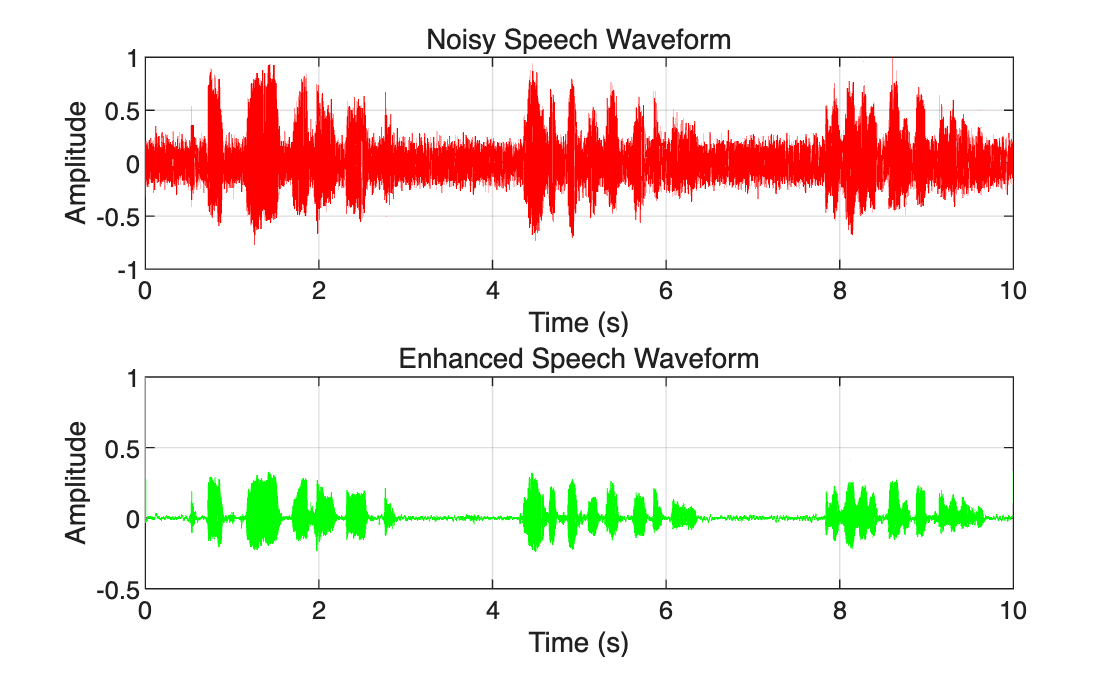

%% 4.6 Compare Noisy and Enhanced Speech

% Plot noisy and enhanced waveforms
figure;

subplot(2,1,1);
plot(t, y, 'r');
grid on;
xlabel('Time (s)');
ylabel('Amplitude');
title('Noisy Speech Waveform');

subplot(2,1,2);
plot(t, enhancedToSave, 'g');
grid on;
xlabel('Time (s)');
ylabel('Amplitude');
title('Enhanced Speech Waveform');

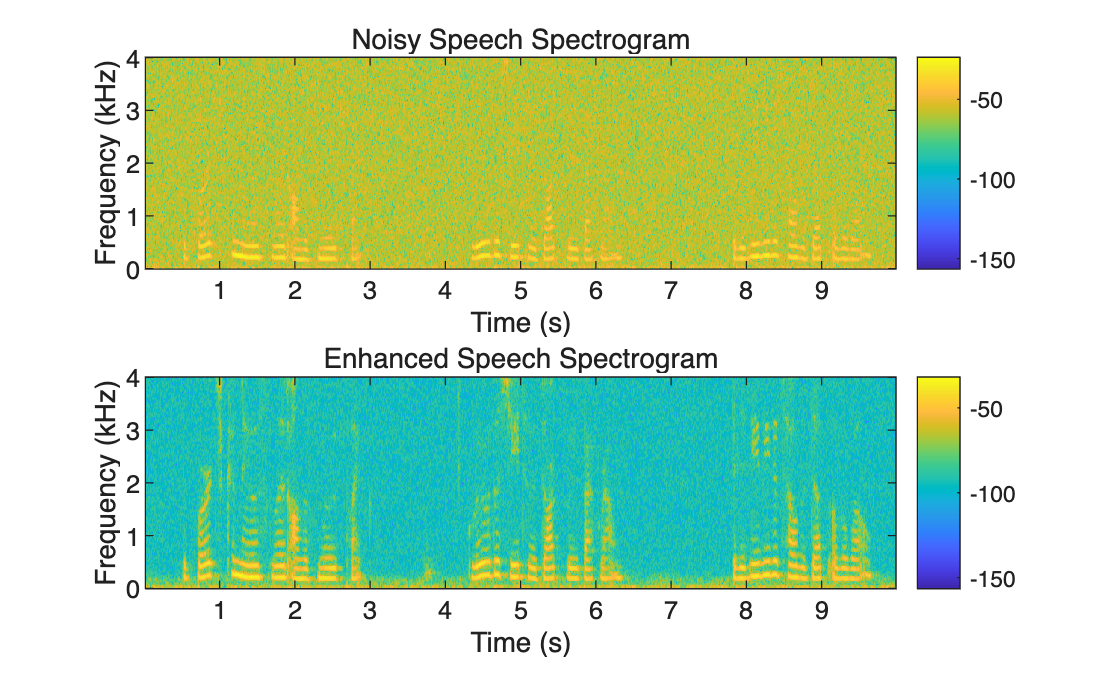


% Plot noisy and enhanced spectrograms
figure;

subplot(2,1,1);
spectrogram(y, win, overlapLength, nfft, fs, 'yaxis');
title('Noisy Speech Spectrogram');
xlabel('Time (s)');
ylabel('Frequency (kHz)');
colorbar;

subplot(2,1,2);
spectrogram(enhancedToSave, win, overlapLength, nfft, fs, 'yaxis');
title('Enhanced Speech Spectrogram');
xlabel('Time (s)');
ylabel('Frequency (kHz)');
colorbar;

The spectrum of the enhanced speech shows that the broadband background energy is lower than that of the noisy speech. After processing, the harmonic structure and voice related structure become clearer, especially in the lower frequency band. This visualization result is consistent with the improvement of signal-to-noise ratio.

The SNR, RMS energy and zero-crossing rate are calculated as:

$\mathrm{SNR} = 10\log_{10}\frac{\sum_n x^2[n]}{\sum_n (x[n]-\hat{x}[n])^2}$ ,

$\mathrm{RMS} = \sqrt{\frac{1}{N}\sum_{n=0}^{N-1}x^2[n]}$ ,

$\mathrm{ZCR} = \frac{1}{2N}\sum_{n=1}^{N-1}|\mathrm{sgn}(x[n])-\mathrm{sgn}(x[n-1])|$ .

%% 4.7 Feature-Based Evaluation of the Main 5 dB Experiment

% RMS energy
rmsClean = sqrt(mean(x.^2));
rmsNoisy = sqrt(mean(y.^2));
rmsEnhanced = sqrt(mean(enhancedToSave.^2));

% Zero-crossing rate
zcrClean = sum(abs(diff(sign(x)))) / (2 * length(x));
zcrNoisy = sum(abs(diff(sign(y)))) / (2 * length(y));
zcrEnhanced = sum(abs(diff(sign(enhancedToSave)))) / (2 * length(enhancedToSave));

% Display RMS and ZCR results in a feature table
featureNames = {'Clean Speech'; 'Noisy Speech'; 'Enhanced Speech'};
rmsValues = [rmsClean; rmsNoisy; rmsEnhanced];
zcrValues = [zcrClean; zcrNoisy; zcrEnhanced];

featureTable = table(featureNames, rmsValues, zcrValues, ...
    'VariableNames', {'Signal', 'RMS_Energy', 'Zero_Crossing_Rate'});

disp(featureTable);

          Signal           RMS_Energy    Zero_Crossing_Rate
    ___________________    __________    __________________

    {'Clean Speech'   }      0.14345          0.076275     
    {'Noisy Speech'   }      0.16438           0.35868     
    {'Enhanced Speech'}     0.055225           0.10366     




% Display SNR results separately to avoid assigning SNR to the clean reference signal
snrNames = {'Noisy Input'; 'Enhanced Output'; 'Improvement'};
snrValues = [inputSNR; outputSNR; snrImprovement];

snrTable = table(snrNames, snrValues, ...
    'VariableNames', {'Condition', 'SNR_dB'});

disp(snrTable);

         Condition         SNR_dB
    ___________________    ______

    {'Noisy Input'    }    5.0066
    {'Enhanced Output'}    17.264
    {'Improvement'    }    12.257



To further evaluate the robustness of the STFT-based Wiener-style soft mask, the experiment was repeated at three different input SNR levels: 0 dB, 5 dB, and 10 dB. A lower input SNR represents a more severely corrupted speech signal, while a higher input SNR represents a cleaner noisy recording. For each condition, white Gaussian noise was added to the same clean speech signal, the same STFT parameters were used, and the output SNR was measured after enhancement.

%% 4.8 Effect of Input SNR on Enhancement Performance

snrTargets = [0 5 10];

measuredInputSNR = zeros(length(snrTargets), 1);
measuredOutputSNR = zeros(length(snrTargets), 1);
snrImprovementList = zeros(length(snrTargets), 1);

for s = 1:length(snrTargets)

    currentTargetSNR = snrTargets(s);

    if currentTargetSNR == targetSNR
        % Reuse the main 5 dB experiment exactly, so the reported result is consistent
        testClean = x;
        testNoise = noise;
        testNoisy = y;
    else
        % Generate reproducible noise for the other SNR conditions
        rng(currentTargetSNR);
        testNoise = randn(size(x));

        signalPower = mean(x.^2);
        noisePower = mean(testNoise.^2);

        noiseScale = sqrt(signalPower / ...
            (noisePower * 10^(currentTargetSNR/10)));

        testNoise = noiseScale * testNoise;
        testNoisy = x + testNoise;

        peakValue = max(abs(testNoisy));
        if peakValue > 1
            testClean = x / peakValue;
            testNoise = testNoise / peakValue;
            testNoisy = testNoisy / peakValue;
        else
            testClean = x;
        end
    end

    % STFT analysis
    numFrames = floor((length(testNoisy) - winLength) / hopSize) + 1;
    numFreqBins = nfft/2 + 1;

    XstftTest = zeros(numFreqBins, numFrames);
    YstftTest = zeros(numFreqBins, numFrames);
    NstftTest = zeros(numFreqBins, numFrames);

    for frame = 1:numFrames
        startIndex = (frame - 1) * hopSize + 1;

        xFrame = testClean(startIndex:startIndex + winLength - 1) .* win;
        yFrame = testNoisy(startIndex:startIndex + winLength - 1) .* win;
        nFrame = testNoise(startIndex:startIndex + winLength - 1) .* win;

        Xspec = fft(xFrame, nfft);
        Yspec = fft(yFrame, nfft);
        Nspec = fft(nFrame, nfft);

        XstftTest(:, frame) = Xspec(1:numFreqBins);
        YstftTest(:, frame) = Yspec(1:numFreqBins);
        NstftTest(:, frame) = Nspec(1:numFreqBins);
    end

    % Oracle Wiener-style soft mask
    speechPower = abs(XstftTest).^2;
    noisePower = abs(NstftTest).^2;

    mask = speechPower ./ (speechPower + noisePower + eps);
    mask = 0.05 + 0.95 * mask;

    EnhancedSTFT = mask .* YstftTest;

    % Inverse STFT using overlap-add
    testEnhanced = zeros(length(testNoisy), 1);
    windowSum = zeros(length(testNoisy), 1);

    for frame = 1:numFrames
        startIndex = (frame - 1) * hopSize + 1;

        oneSidedSpectrum = EnhancedSTFT(:, frame);
        fullSpectrum = [oneSidedSpectrum; ...
            conj(oneSidedSpectrum(end-1:-1:2))];

        timeFrame = real(ifft(fullSpectrum, nfft));
        timeFrame = timeFrame(1:winLength);

        testEnhanced(startIndex:startIndex + winLength - 1) = ...
            testEnhanced(startIndex:startIndex + winLength - 1) + timeFrame .* win;

        windowSum(startIndex:startIndex + winLength - 1) = ...
            windowSum(startIndex:startIndex + winLength - 1) + win.^2;
    end

    validIndex = windowSum > 1e-8;
    testEnhanced(validIndex) = testEnhanced(validIndex) ./ windowSum(validIndex);

    % Align amplitude before evaluation
    gain = (testClean' * testEnhanced) / (testEnhanced' * testEnhanced + eps);
    testEnhancedAligned = gain * testEnhanced;

    evalIndex = windowSum > 0.1;

    measuredInputSNR(s) = 10 * log10(mean(testClean(evalIndex).^2) / ...
        mean((testNoisy(evalIndex) - testClean(evalIndex)).^2));

    measuredOutputSNR(s) = 10 * log10(mean(testClean(evalIndex).^2) / ...
        mean((testEnhancedAligned(evalIndex) - testClean(evalIndex)).^2));

    snrImprovementList(s) = measuredOutputSNR(s) - measuredInputSNR(s);
end

snrComparisonTable = table( ...
    snrTargets(:), ...
    measuredInputSNR, ...
    measuredOutputSNR, ...
    snrImprovementList, ...
    'VariableNames', {'Target_SNR_dB', 'Measured_Input_SNR_dB', ...
    'Output_SNR_dB', 'SNR_Improvement_dB'});

disp(snrComparisonTable);

    Target_SNR_dB    Measured_Input_SNR_dB    Output_SNR_dB    SNR_Improvement_dB
    _____________    _____________________    _____________    __________________

          0                0.0066491             13.974              13.968      
          5                   5.0066             17.264              12.257      
         10                   10.003             20.368              10.366      



The multi-SNR evaluation shows that the output SNR is higher than the measured input SNR for all three input noise levels. At 0 dB input SNR, the output SNR increases to 13.97 dB. At 5 dB input SNR, the output SNR is 17.26 dB, which is consistent with the main experiment. At 10 dB input SNR, the output SNR reaches 20.37 dB. The SNR improvement decreases from 13.97 dB to 10.37 dB as the input signal becomes cleaner, because fewer time-frequency bins are dominated by noise.

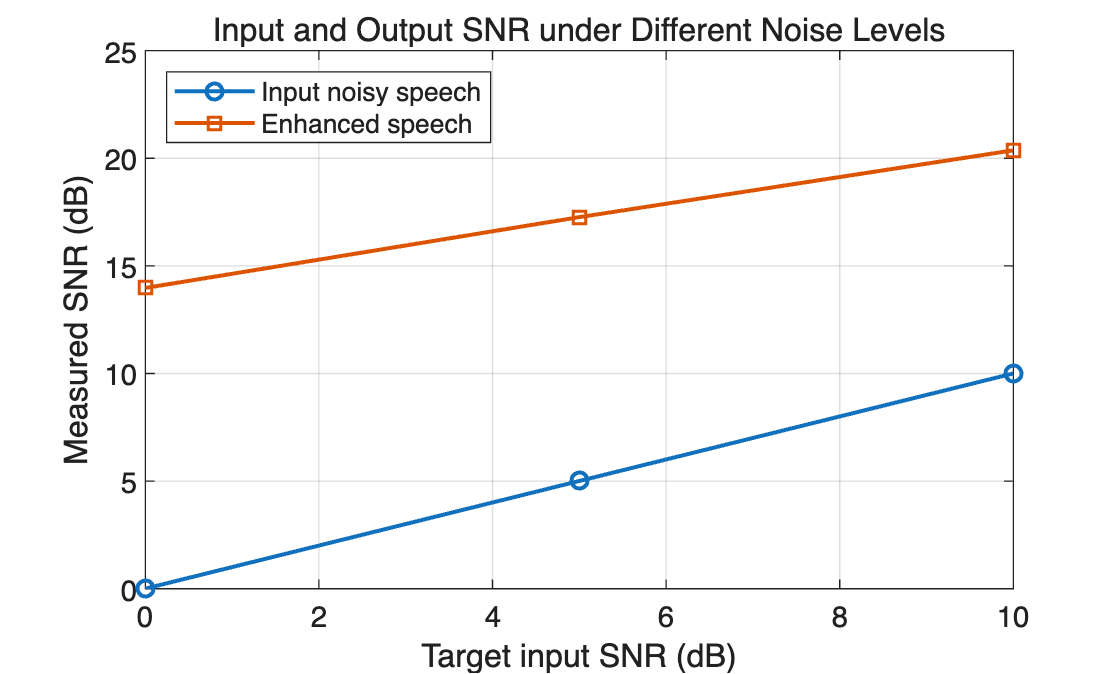

figure;
plot(snrComparisonTable.Target_SNR_dB, ...
    snrComparisonTable.Measured_Input_SNR_dB, '-o', 'LineWidth', 1.5);
hold on;
plot(snrComparisonTable.Target_SNR_dB, ...
    snrComparisonTable.Output_SNR_dB, '-s', 'LineWidth', 1.5);
grid on;
xlabel('Target input SNR (dB)');
ylabel('Measured SNR (dB)');
title('Input and Output SNR under Different Noise Levels');
legend('Input noisy speech', 'Enhanced speech', 'Location', 'northwest');

The SNR comparison plot shows that the enhanced speech consistently achieves a higher SNR than the noisy input under 0 dB, 5 dB, and 10 dB white-noise conditions. This indicates that the STFT-based Wiener-style mask remains effective across different input noise levels.

## 5. Discussion

The experimental results show that the white Gaussian noise has a significant impact on the speech signal in both the time domain and frequency domain. In waveform comparison, noisy signals show stronger background fluctuations, especially in the quiet regions of clean speech. The FFT spectra also show that the noisy signal shows stronger broadband energy in the frequency range of 0-4 kHz, which is consistent with the expected characteristics of white noise.

STFT spectrogram shows the influence of noise more clearly from the perspective of time-frequency. In the clean speech spectrogram, the speech structure shows relatively concentrated harmonic and formant-like structures, mainly distributed in the lower frequency band. In the noisy speech spectrogram, these structures are partially masked by broadband noise. After the application of STFT-based Wiener-style soft mask, the enhanced speech spectrogram shows lower background energy and clearer speech-related structure.

The quantitative results were consistent with the above visual observations. The input signal-to-noise ratio is about 5.01 dB, the output signal-to-noise ratio is about 17.26 dB, and the signal-to-noise ratio is increased by about 12.26 dB, indicating that the enhancement method is effective in this controlled experiment. The comparison of audio features also showed obvious changes: after adding noise, the zero-crossing rate increased significantly from 0.0763 for clean speech to 0.3587 for noisy speech; After enhancement, the zero-crossing rate decreases to 0.1037, which is closer to the value of clean speech.

The multi-SNR experiment further confirms that the enhancement method is effective across different noise levels. For target input SNRs of 0 dB, 5 dB, and 10 dB, the output SNR values are 13.97 dB, 17.26 dB, and 20.37 dB, respectively. The 5 dB result is consistent with the main experiment. The SNR improvement decreases from 13.97 dB to 10.37 dB as the input SNR increases, because the noisy signal already contains clearer speech structure at higher SNR and fewer time-frequency bins are dominated by noise.

However, the RMS energy of the enhanced signal is lower than that of the clean speech, indicating that the mask not only suppresses noise, but also weakens part of the speech energy. This is a common limitation of simple time-frequency enhancement methods. Another limitation is that an oracle mask is used in this experiment, because clean speech and added noise are known under controlled conditions. In real systems, it is usually impossible to obtain clean speech, so it is necessary to estimate speech power and noise power. Nevertheless, this experiment successfully demonstrated the application of sampling, FFT, STFT, windowing, overlap-add reconstruction, and audio feature analysis in speech enhancement.

## 6. Conclusion

This report implements a speech enhancement experiment based on STFT using MATLAB. In the experiment, the clean speech signal from the Open Speech Repository is corrupted with white Gaussian noise, and analyzed by waveform plots, FFT spectra and STFT spectrograms. Then a Wiener-style soft mask is applied in the STFT domain, and the enhanced speech signal is reconstructed by inverse FFT and overlap-add reconstruction.

The experimental results show that this method can effectively suppress the broadband noise, and the signal-to-noise ratio increases from about 5.01 dB to 17.26 dB. The multi-SNR comparison also shows consistent improvement for 0 dB, 5 dB, and 10 dB input conditions, confirming that the method is robust across different white-noise levels rather than only working for a single test case. The zero-crossing rate of the enhanced speech is also closer to the level of clean speech. The main limitation is that this experiment is a controlled experiment, using the known clean speech and noise to construct the mask. Future work can further compare the enhancement effects of noise-estimated masks, spectral subtraction, Wiener filtering and real-world noise recordings.

## 7. References

[1] C. Zheng, H. Zhang, W. Liu, X. Luo, A. Li, X. Li, and B. C. J. Moore, “Sixty years of frequency-domain monaural speech enhancement: From traditional to deep learning methods,” Trends in Hearing, vol. 27, pp. 1-31, 2023, doi: 10.1177/23312165231209913.

[2] J. B. Allen and L. R. Rabiner, “A unified approach to short-time Fourier analysis and synthesis,” Proceedings of the IEEE, vol. 65, no. 11, pp. 1558-1564, Nov. 1977, doi: 10.1109/PROC.1977.10770.

[3] P. C. Loizou, Speech Enhancement: Theory and Practice, 2nd ed. Boca Raton, FL, USA: CRC Press, 2013.

[4] Open Speech Repository, “American English speech files.” Available: [https://www.voiptroubleshooter.com/open_speech/american.html](https://www.voiptroubleshooter.com/open_speech/american.html). 

[5] MathWorks, “Spectrogram using short-time Fourier transform.” Available: [https://www.mathworks.com/help/signal/ref/spectrogram.html](https://www.mathworks.com/help/signal/ref/spectrogram.html). 